# Getting Started with MATLAB Support Package for Arduino Hardware

This example shows how to use MATLAB® Support Package for Arduino® Hardware to perform basic operations on the hardware such as turning an LED on and off and blinking LEDs.

## Hardware setup

Connect an LED to digital pin 11 on the Arduino hardware through a 1kOhm resistor.

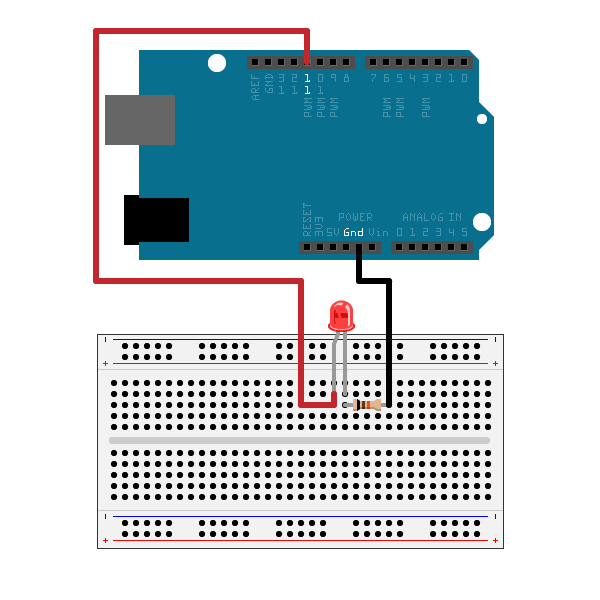

## Create an arduino object

warning('off','all')
a = arduino();

Error creating transport for the connection. Try the previous operation again. If the issue persists, restart MATLAB Connector and try again.

If you have more than one Arduino board connected, specify the port and board type.

% clear a;
% a = arduino('COM4', 'Uno');

## Turn LED on and off

Write value `1` or true to digital pin 11 turns on the LED and write a value of 0 or false turns it off. Execute the following command at the MATLAB prompt to turn the LED off and on.

writeDigitalPin(a, 'D11', 0);
pause(2);
writeDigitalPin(a, 'D11', 1);

Configure the LED to blink at a period of 0.5 second.

for i = 1:10
    writeDigitalPin(a, 'D11', 0);
    pause(0.5);
    writeDigitalPin(a, 'D11', 1);
    pause(0.5);
end

## Brighten and dim LED

Send pulse signals of specified width to the PWM pins on the Arduino hardware. PWM signals can light up LEDs connected to the pin. The duty cycle of the pulse controls the brightness of the LED. Calculate the amount that the LED brightens and dims by dividing the max and min duty cycle for the pin by the number of iterations.

brightness_step = (1-0)/20;
for i = 1:20
    writePWMDutyCycle(a, 'D11', i*brightness_step);
    pause(0.1);
end

for i = 1:20
    writePWMDutyCycle(a, 'D11', 1-i*brightness_step);
    pause(0.1);
end

You can also brighten and dim the lights by changing the voltage of the PWM signal. Calculate the amount that the LED brightens and dims by dividing the max and min voltage for the pin by the number of iterations.

brightness_step = (5-0)/20;
for i = 1:20
    writePWMVoltage(a, 'D11', i*brightness_step);
    pause(0.1);
end

for i = 1:20
    writePWMVoltage(a, 'D11', 5-i*brightness_step);
    pause(0.1);
end

## Clean up

Once the connection is no longer needed, clear the arduino object.

clear a

© COPYRIGHT 2024 by The MathWorks®, Inc.